close all;
clear all;
clc;
% Parameters
automatically_save_plots = true;
% true -> automatically saves plots in folder
% false -> doesn't automatically save plots

## PART 1 - Neghborhood observer

%% Setup parameters

% Matrices that describe the magnetic levitator
A = [
    0       1;
    880.87  0
];

B = [
    0;
    -9.9453
];

C = [708.27 0];

D = 0;

%Number of follower nodes
N = 6;

% x dimenstionallity
n = size(A,1);

QR_values = [
    [1 100]
    [1 10]
    [1 1]
    [10 1]
    [100 1]
];

[couples_count, ~] = size(QR_values);


% Initial conditions
xhat0 = [0 0]';
x0_followers = [0 0]';

% Sensors noise
sigma_followers= 0.001;
sigma_leader= 0.001;

% SIMULATION WITHOUT NOISE
noise_free = true;
% main loop
for couple_id=1:couples_count %iterate over Q and R values
    Q = QR_values(couple_id, 1)*eye(2);
    R = QR_values(couple_id, 2);

    for topology_num=1:4 %iterate over all topologies
        for ref = ["constant", "sinusoidal", "ramp"] % iterates through all references
        
            fprintf("Working on topology #%d", topology_num);
            
            [Ad, L , G] = compute_topology_matrices(topology_num);
            
            % Coupling Gain
            eigs = eig(L+G);
            c = (0.5/min(real(eigs))) + 0.5;
            
           switch ref
                case "constant"
                    x0=[0.005 0.0]';
                    K_reg = place(A, B, [0, -10]);
                    
                case "sinusoidal"
                    x0= [1 1]';
                    K_reg= place(A,B,[1i -1i]);
                    
                case "ramp"
                    x0= [0 1]';
                    K_reg= acker(A,B, [0 0]);
            end
            
            A_leader=A-B*K_reg;
            A = A_leader;
            
            %check if the system is observable
            Ob = obsv(A_leader,C);
            rank_ob = rank(Ob);
            fprintf("Observability matrix rank is #%d. Hence the system is observable", rank_ob);
            % It is, so: Luenberger Observer for the leader
            Lu_obs = (place(A_leader', C', [-20, -10]))';
            
            
            P = are(A, B*inv(R)*B', Q);
            K = R\B'*P;
                        
            % Calculating F
            Pf= are(A', C'*pinv(R)*C, Q);
            F = Pf*C'/R;
            
            
            % Check if Ac is Hurwitz
            ac_term1 = kron(eye(N), A);
            ac_term2 = c * kron((L + G), B * K);
            Ac = ac_term1 - ac_term2;
            
            eig_Ac = eig(Ac);
            
            ac_max_real_val = max(real(eig_Ac));
            
            if ac_max_real_val < -1e-6 % Tolerance to avoid numerical errors
                fprintf('  [OK] Topology #%d: Ac IS Hurwitz (Max Re(eig) = %.4f). The global disagreement error will tend to 0.\n', topology_num, ac_max_real_val);
            else
                fprintf('  [WARNING] Topology #%d: Ac IS NOT  Hurwitz (Max Re(eig) = %.4f). The system is not stable!\n', topology_num, ac_max_real_val);
            end
            
            % Check if Ac is Hurwitz
            ao_term1 = kron(eye(N), A);
            ao_term2 = c * kron((L + G), F*C);
            Ao = ao_term1 - ao_term2;
            
            eig_Ao = eig(Ao);
            
            ao_max_real_val = max(real(eig_Ao));
            
            if ao_max_real_val < -1e-6 % Tolerance to avoid numerical errors
                fprintf('  [OK] Topology #%d: Ao IS Hurwitz (Max Re(eig_Ao) = %.4f). The global state estimation error will tend to 0.\n', topology_num, ao_max_real_val);
            else
                fprintf('  [WARNING] Topology #%d: Ao IS NOT  Hurwitz (Max Re(eig_Ao) = %.4f). The global state estimation error will NOT tend to 0!\n', topology_num, ao_max_real_val);
            end
            
            % System Simulation
            t = 200.0;
            out = sim("model_neighborhood_observer.slx", t);
            
            
            
            %%%%% Get simulation outputs
            %Followers Output
            y1 = get(out,"y1");
            y2 = get(out,"y2");
            y3 = get(out,"y3");
            y4 = get(out,"y4");
            y5 = get(out,"y5");
            y6 = get(out,"y6");
            
            %State 1 of each follower
            x11 = get(out,"x11");
            x21 = get(out,"x21");
            x31 = get(out,"x31");
            x41 = get(out,"x41");
            x51 = get(out,"x51");
            x61 = get(out,"x61");
            
            %State 2 of each follower
            x12 = get(out,"x12"); 
            x22 = get(out,"x22"); 
            x32 = get(out,"x32"); 
            x42 = get(out,"x42"); 
            x52 = get(out,"x52"); 
            x62 = get(out,"x62"); 
            
            % Global disagreement error on x1
            delta11 = get(out,"delta11"); 
            delta21 = get(out,"delta21"); 
            delta31 = get(out,"delta31"); 
            delta41 = get(out,"delta41"); 
            delta51 = get(out,"delta51"); 
            delta61 = get(out,"delta61"); 
            
            % Global disagreement error on x2
            delta12 = get(out,"delta12"); 
            delta22 = get(out,"delta22"); 
            delta32 = get(out,"delta32"); 
            delta42 = get(out,"delta42"); 
            delta52 = get(out,"delta52"); 
            delta62 = get(out,"delta62"); 
            
            %Leader Output
            y_leader = get(out,"y0");
            
            %State 1 of the leader
            x_leader_1 = get(out,"x01");
            
            %State 2 of the leader
            x_leader_2 = get(out,"x02");
            
            %Simulation Time
            T = get(out,"T");

            delta_tol = 0.001;            
            % Convergence time for each node (when delta is less then delta_tol
            d11_conv = abs(delta11)<delta_tol;
            t11_conv = min(T(d11_conv));
            
            d21_conv = abs(delta21)<delta_tol;
            t21_conv = min(T(d21_conv));
            
            d31_conv = abs(delta31)<delta_tol;
            t31_conv = min(T(d31_conv));
            
            d41_conv = abs(delta41)<delta_tol;
            t41_conv = min(T(d41_conv));
            
            d51_conv = abs(delta51)<delta_tol;
            t51_conv = min(T(d51_conv));
            
            d61_conv = abs(delta61)<delta_tol;
            t61_conv = min(T(d61_conv));
            
            d12_conv = abs(delta11)<delta_tol;
            t12_conv = min(T(d12_conv));
            
            d22_conv = abs(delta22)<delta_tol;
            t22_conv = min(T(d22_conv));
            
            d32_conv = abs(delta32)<delta_tol;
            t32_conv = min(T(d32_conv));
            
            d42_conv = abs(delta42)<delta_tol;
            t42_conv = min(T(d42_conv));
            
            d52_conv = abs(delta52)<delta_tol;
            t52_conv = min(T(d52_conv));
            
            d62_conv = abs(delta62)<delta_tol;
            t62_conv = min(T(d62_conv));
            
            % Convergence time of the system, computed as the convergence time of the slowest node
            t_conv = max([t11_conv, t21_conv, t31_conv, t41_conv, t51_conv, t61_conv, t12_conv, t22_conv, t32_conv, t42_conv, t52_conv, t62_conv])
            
            
            %%%%%%%%%% PLOT RESULTS
            % String to append in the plot titles
            append_me = "Neighborhood observer | Q: " + num2str(Q(1:1)) + "I, R: " + num2str(R) + ", ref: " + ref + ' noise: ' + ~noise_free + '| ';
            fprintf(' %sConvergence time: %.3f s', append_me, t_conv);

            close all
            
            if automatically_save_plots
                % Create folder
                folder_name = create_folder(noise_free, topology_num, ref, Q, R, "neighborhood_observer");
            end
            
            figure
            hold on
            plot(T,y1)
            plot(T,y2)
            plot(T,y3)
            plot(T,y4)
            plot(T,y5)
            plot(T,y6)
            plot(T,y_leader,"--")
            legend([ 
                "$y_{1}$"
                "$y_{2}$"
                "$y_{3}$"
                "$y_{4}$"
                "$y_{5}$"
                "$y_{6}$"
                "$y_{l}$"
            ],"Interpreter","latex")
            title(append_me + "Output ($y$)","Interpreter","latex")
            xlabel("$t$","Interpreter","latex")

            if automatically_save_plots
                if ispc
                    saveas(gcf, folder_name+'\output.jpg');
                else
                    saveas(gcf, folder_name+'/output.jpg');
                end
            end
            
            hold off
            
            %Plot state 1
            figure
            hold on
            plot(T,x11)
            plot(T,x21)
            plot(T,x31)
            plot(T,x41)
            plot(T,x51)
            plot(T,x61)
            plot(T,x_leader_1,"--")
            legend([ 
                "Follower 1 $x_{1}$"
                "Follower 2 $x_{1}$"
                "Follower 3 $x_{1}$"
                "Follower 4 $x_{1}$"
                "Follower 5 $x_{1}$"
                "Follower 6 $x_{1}$"
                "Leader $x_{1}$"
            ],"Interpreter","latex")
            title(append_me + "State 1 ($x_{1}$)", "Interpreter","latex")
            xlabel("$t$","Interpreter","latex")
            hold off

            if automatically_save_plots
                if ispc
                    saveas(gcf, folder_name+'\state1.jpg');
                else
                    saveas(gcf, folder_name+'/state1.jpg');
                end
            end
            
            %Plot state 2
            figure
            hold on
            plot(T,x12)
            plot(T,x22)
            plot(T,x32)
            plot(T,x42)
            plot(T,x52)
            plot(T,x62)
            plot(T,x_leader_2,"--")
            legend([ 
                "Follower 1 $x_{2}$"
                "Follower 2 $x_{2}$"
                "Follower 3 $x_{2}$"
                "Follower 4 $x_{2}$"
                "Follower 5 $x_{2}$"
                "Follower 6 $x_{2}$"
                "Leader $x_{2}$"
            ],"Interpreter","latex")
            title(append_me + "State 2 ($x_{2}$)","Interpreter","latex")
            xlabel("$t$","Interpreter","latex")
            hold off

            if automatically_save_plots
                if ispc
                    saveas(gcf, folder_name+'\state2.jpg');
                else
                    saveas(gcf, folder_name+'/state2.jpg');
                end
            end
            
            %Plot neighborhood tracking error on state 1
            figure
            hold on
            plot(T,delta11)
            plot(T,delta21)
            plot(T,delta31)
            plot(T,delta41)
            plot(T,delta51)
            plot(T,delta61)
            legend([ 
                "Follower 1 $delta_{1}$"
                "Follower 2 $delta_{1}$"
                "Follower 3 $delta_{1}$"
                "Follower 4 $delta_{1}$"
                "Follower 5 $delta_{1}$"
                "Follower 6 $delta_{1}$"
            ],"Interpreter","latex")
            title(append_me + "Global disagreement error on state ($x_{1}$)","Interpreter","latex")
            xlabel("$t$","Interpreter","latex")
            hold off

            if automatically_save_plots
                if ispc
                    saveas(gcf, folder_name+'\disagreement_x1.jpg');
                else
                    saveas(gcf, folder_name+'/disagreement_x1.jpg');
                end
            end
            
            %Plot neighborhood tracking error on state 2
            figure
            hold on
            plot(T,delta12)
            plot(T,delta22)
            plot(T,delta32)
            plot(T,delta42)
            plot(T,delta52)
            plot(T,delta62)
            legend([ 
                "Follower 1 $delta_{1}$"
                "Follower 2 $delta_{1}$"
                "Follower 3 $delta_{1}$"
                "Follower 4 $delta_{1}$"
                "Follower 5 $delta_{1}$"
                "Follower 6 $delta_{1}$"
            ],"Interpreter","latex")
            title(append_me + "Global disagreement error on state ($x_{2}$)","Interpreter","latex")
            xlabel("$t$","Interpreter","latex")
            hold off

            if automatically_save_plots
                if ispc
                    saveas(gcf, folder_name+'\disagreement_x2.jpg');
                else
                    saveas(gcf, folder_name+'/disagreement_x2.jpg');
                end
            end
        end
    end
end

## PART 2 - Local observers

**N.B:** The following code IS THE SAME AS PART 1. The only difference is the simulink model used (in this case, model_local_observers)

%% Setup parameters

% Matrices that describe the magnetic levitator
A = [
    0       1;
    880.87  0
];

B = [
    0;
    -9.9453
];

C = [708.27 0];

D = 0;

%Number of follower nodes
N = 6;

% x dimenstionallity
n = size(A,1);

QR_values = [
    [1 100]
    [1 10]
    [1 1]
    [10 1]
    [100 1]
];

[couples_count, ~] = size(QR_values);


% Initial conditions
xhat0 = [0 0]';
x0_followers = [0 0]';

% Sensors noise
sigma_followers= 0.001;
sigma_leader= 0.001;

Working on topology #1

Observability matrix rank is #2. Hence the system is observable

  [OK] Topology #1: Ac IS Hurwitz (Max Re(eig) = -0.0990). The global disagreement error will tend to 0.


  [OK] Topology #1: Ao IS Hurwitz (Max Re(eig_Ao) = -10.0509). The global state estimation error will tend to 0.


t_conv = 30.4000

 Q: 1I, R: 100, ref: constant noise: false| Convergence time: 30.400 s

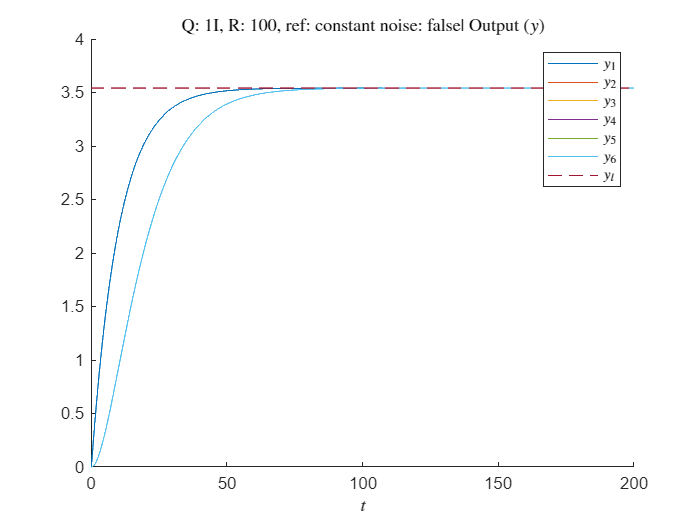

% SIMULATION WITHOUT NOISE
noise_free = true;
% main loop
for couple_id=1:couples_count %iterate over Q and R values
    Q = QR_values(couple_id, 1)*eye(2);
    R = QR_values(couple_id, 2);

    for topology_num=1:4 %iterate over all topologies
        for ref = ["constant", "sinusoidal", "ramp"] % iterates through all references
        
            fprintf("Working on topology #%d", topology_num);
            
            [Ad, L , G] = compute_topology_matrices(topology_num);
            
            % Coupling Gain
            eigs = eig(L+G);
            c = (0.5/min(real(eigs))) + 0.5;
            
           switch ref
                case "constant"
                    x0=[0.005 0.0]';
                    K_reg = place(A, B, [0, -10]);
                    
                case "sinusoidal"
                    x0= [1 1]';
                    K_reg= place(A,B,[1i -1i]);
                    
                case "ramp"
                    x0= [0 1]';
                    K_reg= acker(A,B, [0 0]);
            end
            
            A_leader=A-B*K_reg;
            A = A_leader;
            
            %check if the system is observable
            Ob = obsv(A_leader,C);
            rank_ob = rank(Ob);
            fprintf("Observability matrix rank is #%d. Hence the system is observable", rank_ob);
            % It is, so: Luenberger Observer for the leader
            Lu_obs = (place(A_leader', C', [-20, -10]))';
            
            
            P = are(A, B*inv(R)*B', Q);
            K = R\B'*P;
                        
            % Calculating F
            Pf= are(A', C'*pinv(R)*C, Q);
            F = Pf*C'/R;
            
            
            % Check if Ac is Hurwitz
            ac_term1 = kron(eye(N), A);
            ac_term2 = c * kron((L + G), B * K);
            Ac = ac_term1 - ac_term2;
            
            eig_Ac = eig(Ac);
            
            ac_max_real_val = max(real(eig_Ac));
            
            if ac_max_real_val < -1e-6 % Tolerance to avoid numerical errors
                fprintf('  [OK] Topology #%d: Ac IS Hurwitz (Max Re(eig) = %.4f). The global disagreement error will tend to 0.\n', topology_num, ac_max_real_val);
            else
                fprintf('  [WARNING] Topology #%d: Ac IS NOT  Hurwitz (Max Re(eig) = %.4f). The system is not stable!\n', topology_num, ac_max_real_val);
            end
            
            % Check if Ac is Hurwitz
            ao_term1 = kron(eye(N), A);
            ao_term2 = c * kron((L + G), F*C);
            Ao = ao_term1 - ao_term2;
            
            eig_Ao = eig(Ao);
            
            ao_max_real_val = max(real(eig_Ao));
            
            if ao_max_real_val < -1e-6 % Tolerance to avoid numerical errors
                fprintf('  [OK] Topology #%d: Ao IS Hurwitz (Max Re(eig_Ao) = %.4f). The global state estimation error will tend to 0.\n', topology_num, ao_max_real_val);
            else
                fprintf('  [WARNING] Topology #%d: Ao IS NOT  Hurwitz (Max Re(eig_Ao) = %.4f). The global state estimation error will NOT tend to 0!\n', topology_num, ao_max_real_val);
            end
            
            % System Simulation
            t = 200.0;
            out = sim("model_local_observers.slx", t);
            
            
            
            %%%%% Get simulation outputs
            %Followers Output
            y1 = get(out,"y1");
            y2 = get(out,"y2");
            y3 = get(out,"y3");
            y4 = get(out,"y4");
            y5 = get(out,"y5");
            y6 = get(out,"y6");
            
            %State 1 of each follower
            x11 = get(out,"x11");
            x21 = get(out,"x21");
            x31 = get(out,"x31");
            x41 = get(out,"x41");
            x51 = get(out,"x51");
            x61 = get(out,"x61");
            
            %State 2 of each follower
            x12 = get(out,"x12"); 
            x22 = get(out,"x22"); 
            x32 = get(out,"x32"); 
            x42 = get(out,"x42"); 
            x52 = get(out,"x52"); 
            x62 = get(out,"x62"); 
            
            % Global disagreement error on x1
            delta11 = get(out,"delta11"); 
            delta21 = get(out,"delta21"); 
            delta31 = get(out,"delta31"); 
            delta41 = get(out,"delta41"); 
            delta51 = get(out,"delta51"); 
            delta61 = get(out,"delta61"); 
            
            % Global disagreement error on x2
            delta12 = get(out,"delta12"); 
            delta22 = get(out,"delta22"); 
            delta32 = get(out,"delta32"); 
            delta42 = get(out,"delta42"); 
            delta52 = get(out,"delta52"); 
            delta62 = get(out,"delta62"); 
            
            %Leader Output
            y_leader = get(out,"y0");
            
            %State 1 of the leader
            x_leader_1 = get(out,"x01");
            
            %State 2 of the leader
            x_leader_2 = get(out,"x02");
            
            %Simulation Time
            T = get(out,"T");

            delta_tol = 0.001;            
            % Convergence time for each node (when delta is less then delta_tol
            d11_conv = abs(delta11)<delta_tol;
            t11_conv = min(T(d11_conv));
            
            d21_conv = abs(delta21)<delta_tol;
            t21_conv = min(T(d21_conv));
            
            d31_conv = abs(delta31)<delta_tol;
            t31_conv = min(T(d31_conv));
            
            d41_conv = abs(delta41)<delta_tol;
            t41_conv = min(T(d41_conv));
            
            d51_conv = abs(delta51)<delta_tol;
            t51_conv = min(T(d51_conv));
            
            d61_conv = abs(delta61)<delta_tol;
            t61_conv = min(T(d61_conv));
            
            d12_conv = abs(delta11)<delta_tol;
            t12_conv = min(T(d12_conv));
            
            d22_conv = abs(delta22)<delta_tol;
            t22_conv = min(T(d22_conv));
            
            d32_conv = abs(delta32)<delta_tol;
            t32_conv = min(T(d32_conv));
            
            d42_conv = abs(delta42)<delta_tol;
            t42_conv = min(T(d42_conv));
            
            d52_conv = abs(delta52)<delta_tol;
            t52_conv = min(T(d52_conv));
            
            d62_conv = abs(delta62)<delta_tol;
            t62_conv = min(T(d62_conv));
            
            % Convergence time of the system, computed as the convergence time of the slowest node
            t_conv = max([t11_conv, t21_conv, t31_conv, t41_conv, t51_conv, t61_conv, t12_conv, t22_conv, t32_conv, t42_conv, t52_conv, t62_conv])
            
            
            %%%%%%%%%% PLOT RESULTS
            % String to append in the plot titles
            append_me = "Local observers | Q: " + num2str(Q(1:1)) + "I, R: " + num2str(R) + ", ref: " + ref + ' noise: ' + ~noise_free + '| ';
            fprintf(' %sConvergence time: %.3f s', append_me, t_conv);

            close all
            
            if automatically_save_plots
                % Create folder
                folder_name = create_folder(noise_free, topology_num, ref, Q, R, "local_observers");
            end
            
            figure
            hold on
            plot(T,y1)
            plot(T,y2)
            plot(T,y3)
            plot(T,y4)
            plot(T,y5)
            plot(T,y6)
            plot(T,y_leader,"--")
            legend([ 
                "$y_{1}$"
                "$y_{2}$"
                "$y_{3}$"
                "$y_{4}$"
                "$y_{5}$"
                "$y_{6}$"
                "$y_{l}$"
            ],"Interpreter","latex")
            title(append_me + "Output ($y$)","Interpreter","latex")
            xlabel("$t$","Interpreter","latex")

            if automatically_save_plots
                if ispc
                    saveas(gcf, folder_name+'\output.jpg');
                else
                    saveas(gcf, folder_name+'/output.jpg');
                end
            end
            
            hold off
            
            %Plot state 1
            figure
            hold on
            plot(T,x11)
            plot(T,x21)
            plot(T,x31)
            plot(T,x41)
            plot(T,x51)
            plot(T,x61)
            plot(T,x_leader_1,"--")
            legend([ 
                "Follower 1 $x_{1}$"
                "Follower 2 $x_{1}$"
                "Follower 3 $x_{1}$"
                "Follower 4 $x_{1}$"
                "Follower 5 $x_{1}$"
                "Follower 6 $x_{1}$"
                "Leader $x_{1}$"
            ],"Interpreter","latex")
            title(append_me + "State 1 ($x_{1}$)", "Interpreter","latex")
            xlabel("$t$","Interpreter","latex")
            hold off

            if automatically_save_plots
                if ispc
                    saveas(gcf, folder_name+'\state1.jpg');
                else
                    saveas(gcf, folder_name+'/state1.jpg');
                end
            end
            
            %Plot state 2
            figure
            hold on
            plot(T,x12)
            plot(T,x22)
            plot(T,x32)
            plot(T,x42)
            plot(T,x52)
            plot(T,x62)
            plot(T,x_leader_2,"--")
            legend([ 
                "Follower 1 $x_{2}$"
                "Follower 2 $x_{2}$"
                "Follower 3 $x_{2}$"
                "Follower 4 $x_{2}$"
                "Follower 5 $x_{2}$"
                "Follower 6 $x_{2}$"
                "Leader $x_{2}$"
            ],"Interpreter","latex")
            title(append_me + "State 2 ($x_{2}$)","Interpreter","latex")
            xlabel("$t$","Interpreter","latex")
            hold off

            if automatically_save_plots
                if ispc
                    saveas(gcf, folder_name+'\state2.jpg');
                else
                    saveas(gcf, folder_name+'/state2.jpg');
                end
            end
            
            %Plot neighborhood tracking error on state 1
            figure
            hold on
            plot(T,delta11)
            plot(T,delta21)
            plot(T,delta31)
            plot(T,delta41)
            plot(T,delta51)
            plot(T,delta61)
            legend([ 
                "Follower 1 $delta_{1}$"
                "Follower 2 $delta_{1}$"
                "Follower 3 $delta_{1}$"
                "Follower 4 $delta_{1}$"
                "Follower 5 $delta_{1}$"
                "Follower 6 $delta_{1}$"
            ],"Interpreter","latex")
            title(append_me + "Global disagreement error on state ($x_{1}$)","Interpreter","latex")
            xlabel("$t$","Interpreter","latex")
            hold off

            if automatically_save_plots
                if ispc
                    saveas(gcf, folder_name+'\disagreement_x1.jpg');
                else
                    saveas(gcf, folder_name+'/disagreement_x1.jpg');
                end
            end
            
            %Plot neighborhood tracking error on state 2
            figure
            hold on
            plot(T,delta12)
            plot(T,delta22)
            plot(T,delta32)
            plot(T,delta42)
            plot(T,delta52)
            plot(T,delta62)
            legend([ 
                "Follower 1 $delta_{1}$"
                "Follower 2 $delta_{1}$"
                "Follower 3 $delta_{1}$"
                "Follower 4 $delta_{1}$"
                "Follower 5 $delta_{1}$"
                "Follower 6 $delta_{1}$"
            ],"Interpreter","latex")
            title(append_me + "Global disagreement error on state ($x_{2}$)","Interpreter","latex")
            xlabel("$t$","Interpreter","latex")
            hold off

            if automatically_save_plots
                if ispc
                    saveas(gcf, folder_name+'\disagreement_x2.jpg');
                else
                    saveas(gcf, folder_name+'/disagreement_x2.jpg');
                end
            end
        end
    end
end